# Preserve Existing Column Widths

Preserve the existing column widths of a spreadsheet file when you append data to the bottom of the file.

Create workspace variables with text data, then create a table as a container for the variables.

state = {'Massachussetts';'California';'Minnesota';'Virginia'};
stateFlower = {'Trailing arbutus';'Golden Poppy';'Pink and White Lady''s Slipper';'Flowering dogwood'};
stateBird = {'Black-capped chickadee';'California Valley Quail';'Common Loon';'Cardinal'};
data = table(state,stateFlower,stateBird);

Write the table to a spreadsheet file named `states_funfacts.xlsx`. 

writetable(data,'state_funfacts.xlsx')

Create another table of text data.

t = table({'Maryland';'New York'},{'Black-eyed Susan';'Rose'},{'Baltimore oriole';'Eastern bluebird'});

 Append the table to the existing spreadsheet file. Specify `'AutoFitWidth'` as `false` to preserve the existing column widths of the spreadsheet.

writetable(t,'state_funfacts.xlsx',"WriteMode","append","AutoFitWidth",false);

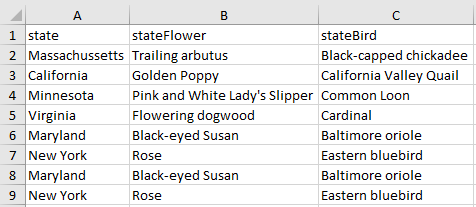

If you specify  `'AutoFitWidth'` as `true` instead of `false`, then `writetable` will adjust the column widths of the spreadsheet to fit the data to be written instead of preserving the original columns widths.

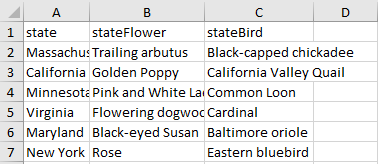

*Copyright 2020 The MathWorks, Inc.*